% Meta 3

% 16. Carrega a estrutura de dados guardada na última meta (Meta 2)
load('AED1.mat', 'tabela');
disp(tabela);

                        Diretorio_Audio                         Nome_Arquivo      Digito    Participante    Repeticao    Sinal_Processado    Taxa_Amostragem    EnergiaTotal    EnergiaPrimeiraMetade    EnergiaSegundaMetade    DesvioPadraoAmplitude      RMS      MediaAmplitude    FatorCrest    TaxaCruzamento    CoeficientesFourier    AmpEspectralMaxima    FreqAmpMaxima    CentroideEspectral    FreqBordaEspectral    LarguraBandaEspectral
    _______________________________________________________    _______________    ______    ____________    _________  


% 17. Seleção das melhores características extraídas
features = {'EnergiaTotal','FatorCrest','TaxaCruzamento', ...
            'CentroideEspectral','FreqBordaEspectral','LarguraBandaEspectral'};
nAmostras = height(tabela);
X = zeros(nAmostras, numel(features));
for i = 1:numel(features)
    X(:, i) = tabela.(features{i});
end
y = tabela.Digito;

%% Classificador de Distância Mínima com Hold-Out (70/30)
cv = cvpartition(nAmostras, 'HoldOut', 0.3);
idxTrain = training(cv); idxTest = test(cv);
X_train = X(idxTrain,:); y_train = y(idxTrain);
X_test  = X(idxTest,:);  y_test  = y(idxTest);
digitos = unique(y_train);
numClasses = numel(digitos);
centroids = zeros(numClasses, size(X,2));
for k = 1:numClasses
    centroids(k,:) = mean(X_train(y_train==digitos(k),:),1);
end
nTest = sum(idxTest);
predicted = zeros(nTest,1);
for i = 1:nTest
    distVec = vecnorm(X_test(i,:)-centroids,2,2);
    [~,minIdx] = min(distVec);
    predicted(i) = digitos(minIdx);
end
%% Avaliação
y_real = y_test;
numAcertos = sum(predicted==y_real);
percentAcertos = (numAcertos/nTest)*100;
fprintf('Acurácia: %d/%d (%.2f%%)\n', numAcertos, nTest, percentAcertos);

Acurácia: 67/150 (44.67%)


C = confusionmat(y_real,predicted);
disp('Matriz de Confusão:'); disp(C);

Matriz de Confusão:
     5     1     9     1     1     0     0     3     0     3
     0    14     0     1     0     0     0     0     2     1
     1     0    10     1     0     1     0     2     0     0
     0     3     0     3     2     3     0     0     0     1
     0     5     0     0     1     3     1     6     1     0
     0     2     0     0     0     3     1     6     0     0
     0     0     0     0     0     0    14     0     0     0
     0     2     1     0     0     0     5     5     2     1
     0     0     0     0     1     2     0     0    10     0
     1     3     0     1     1     0     0     0     2     2



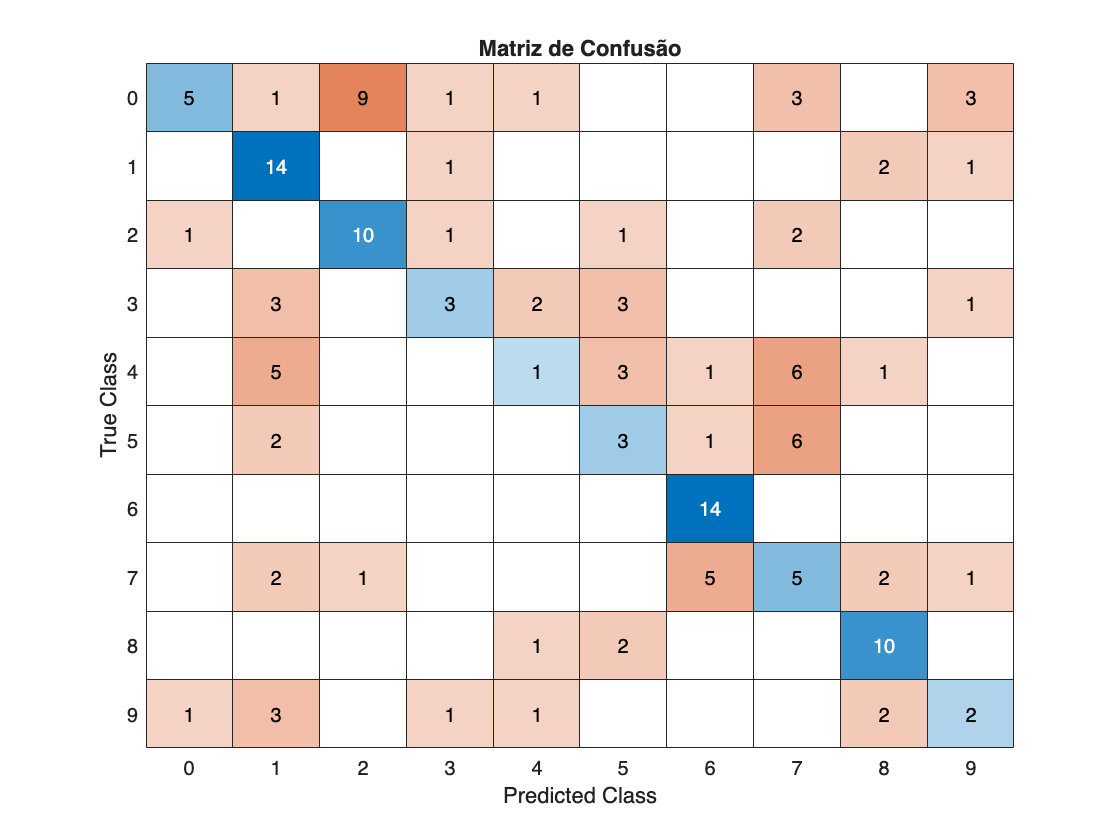

figure('Name','Matriz de Confusão','NumberTitle','off'); confusionchart(y_real,predicted);
title('Matriz de Confusão');

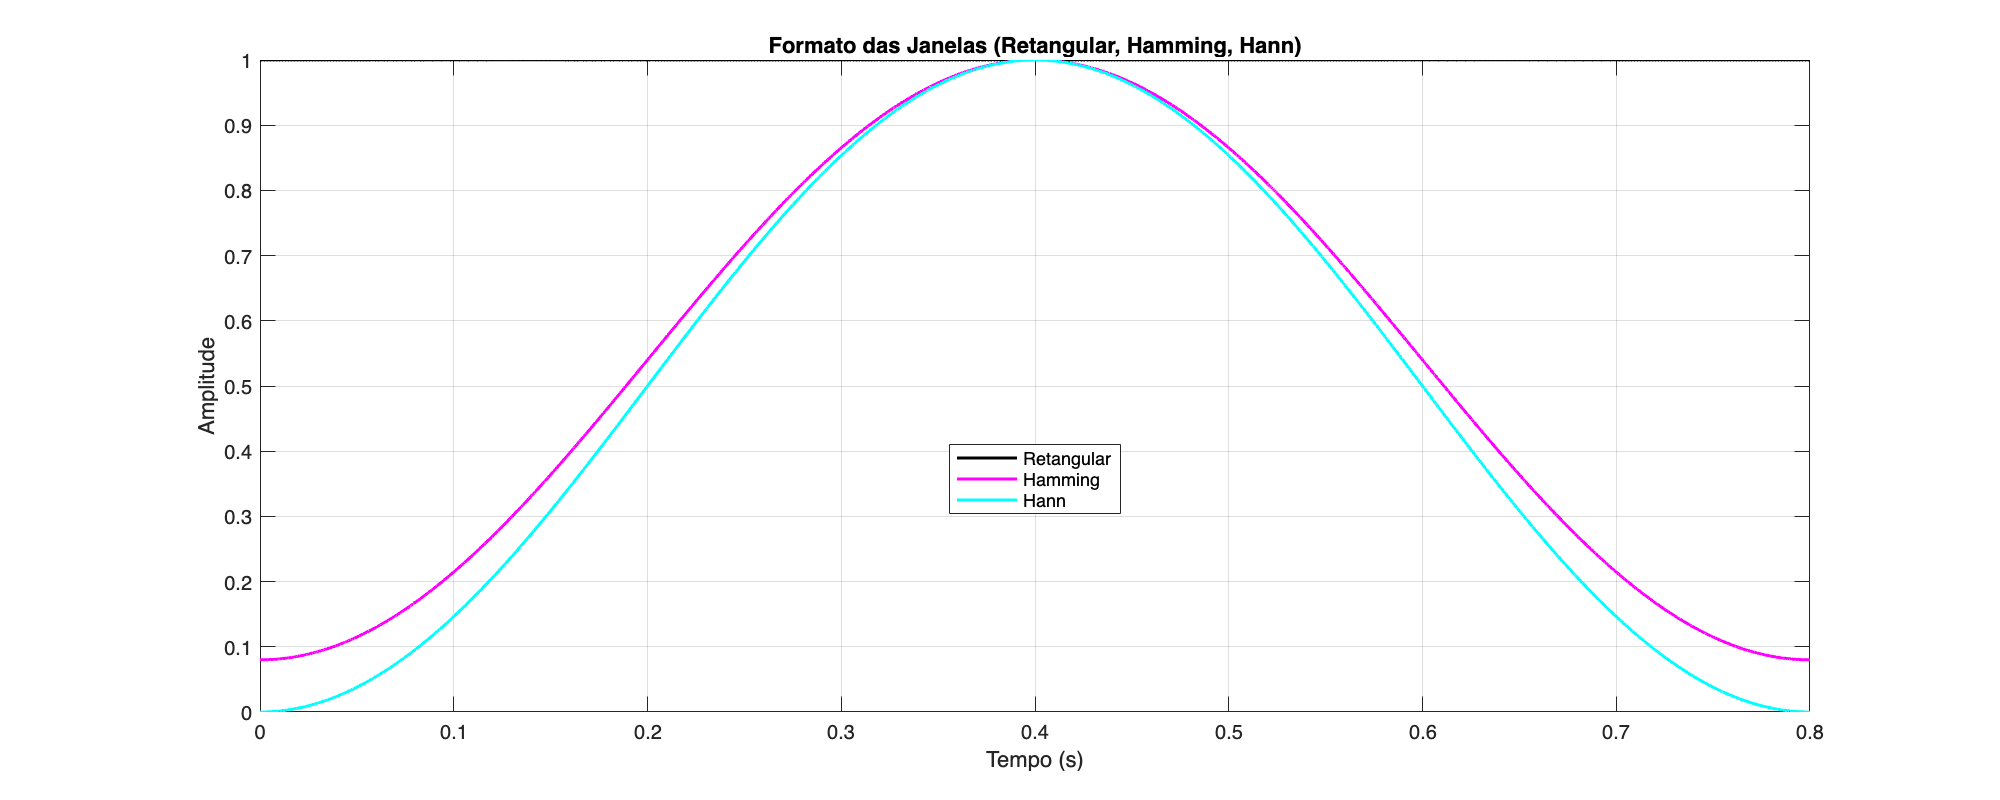


%% Exercício 19: Formato de Janelas (comum a todos os dígitos)
% Seleciona comprimento de amostra de um sinal qualquer (ex: primeiro)
s0 = tabela.Sinal_Processado{1}; fs0 = tabela.Taxa_Amostragem(1);
N0 = length(s0); t0 = (0:N0-1)/fs0;
w_rect0    = ones(N0,1);
w_hamming0 = hamming(N0);
w_hann0    = hann(N0);
figure('Name','Formato das Janelas','NumberTitle','off','Position',[100 100 1000 400]);
plot(t0, w_rect0, 'k', 'LineWidth',1.5); hold on;         % Preto mais visível
plot(t0, w_hamming0, 'm', 'LineWidth',1.5);               % Magenta para contraste
plot(t0, w_hann0, 'c', 'LineWidth',1.5);                  % Ciano distinto
title('Formato das Janelas (Retangular, Hamming, Hann)');
xlabel('Tempo (s)'); ylabel('Amplitude');
legend('Retangular','Hamming','Hann','Location','best'); grid on;

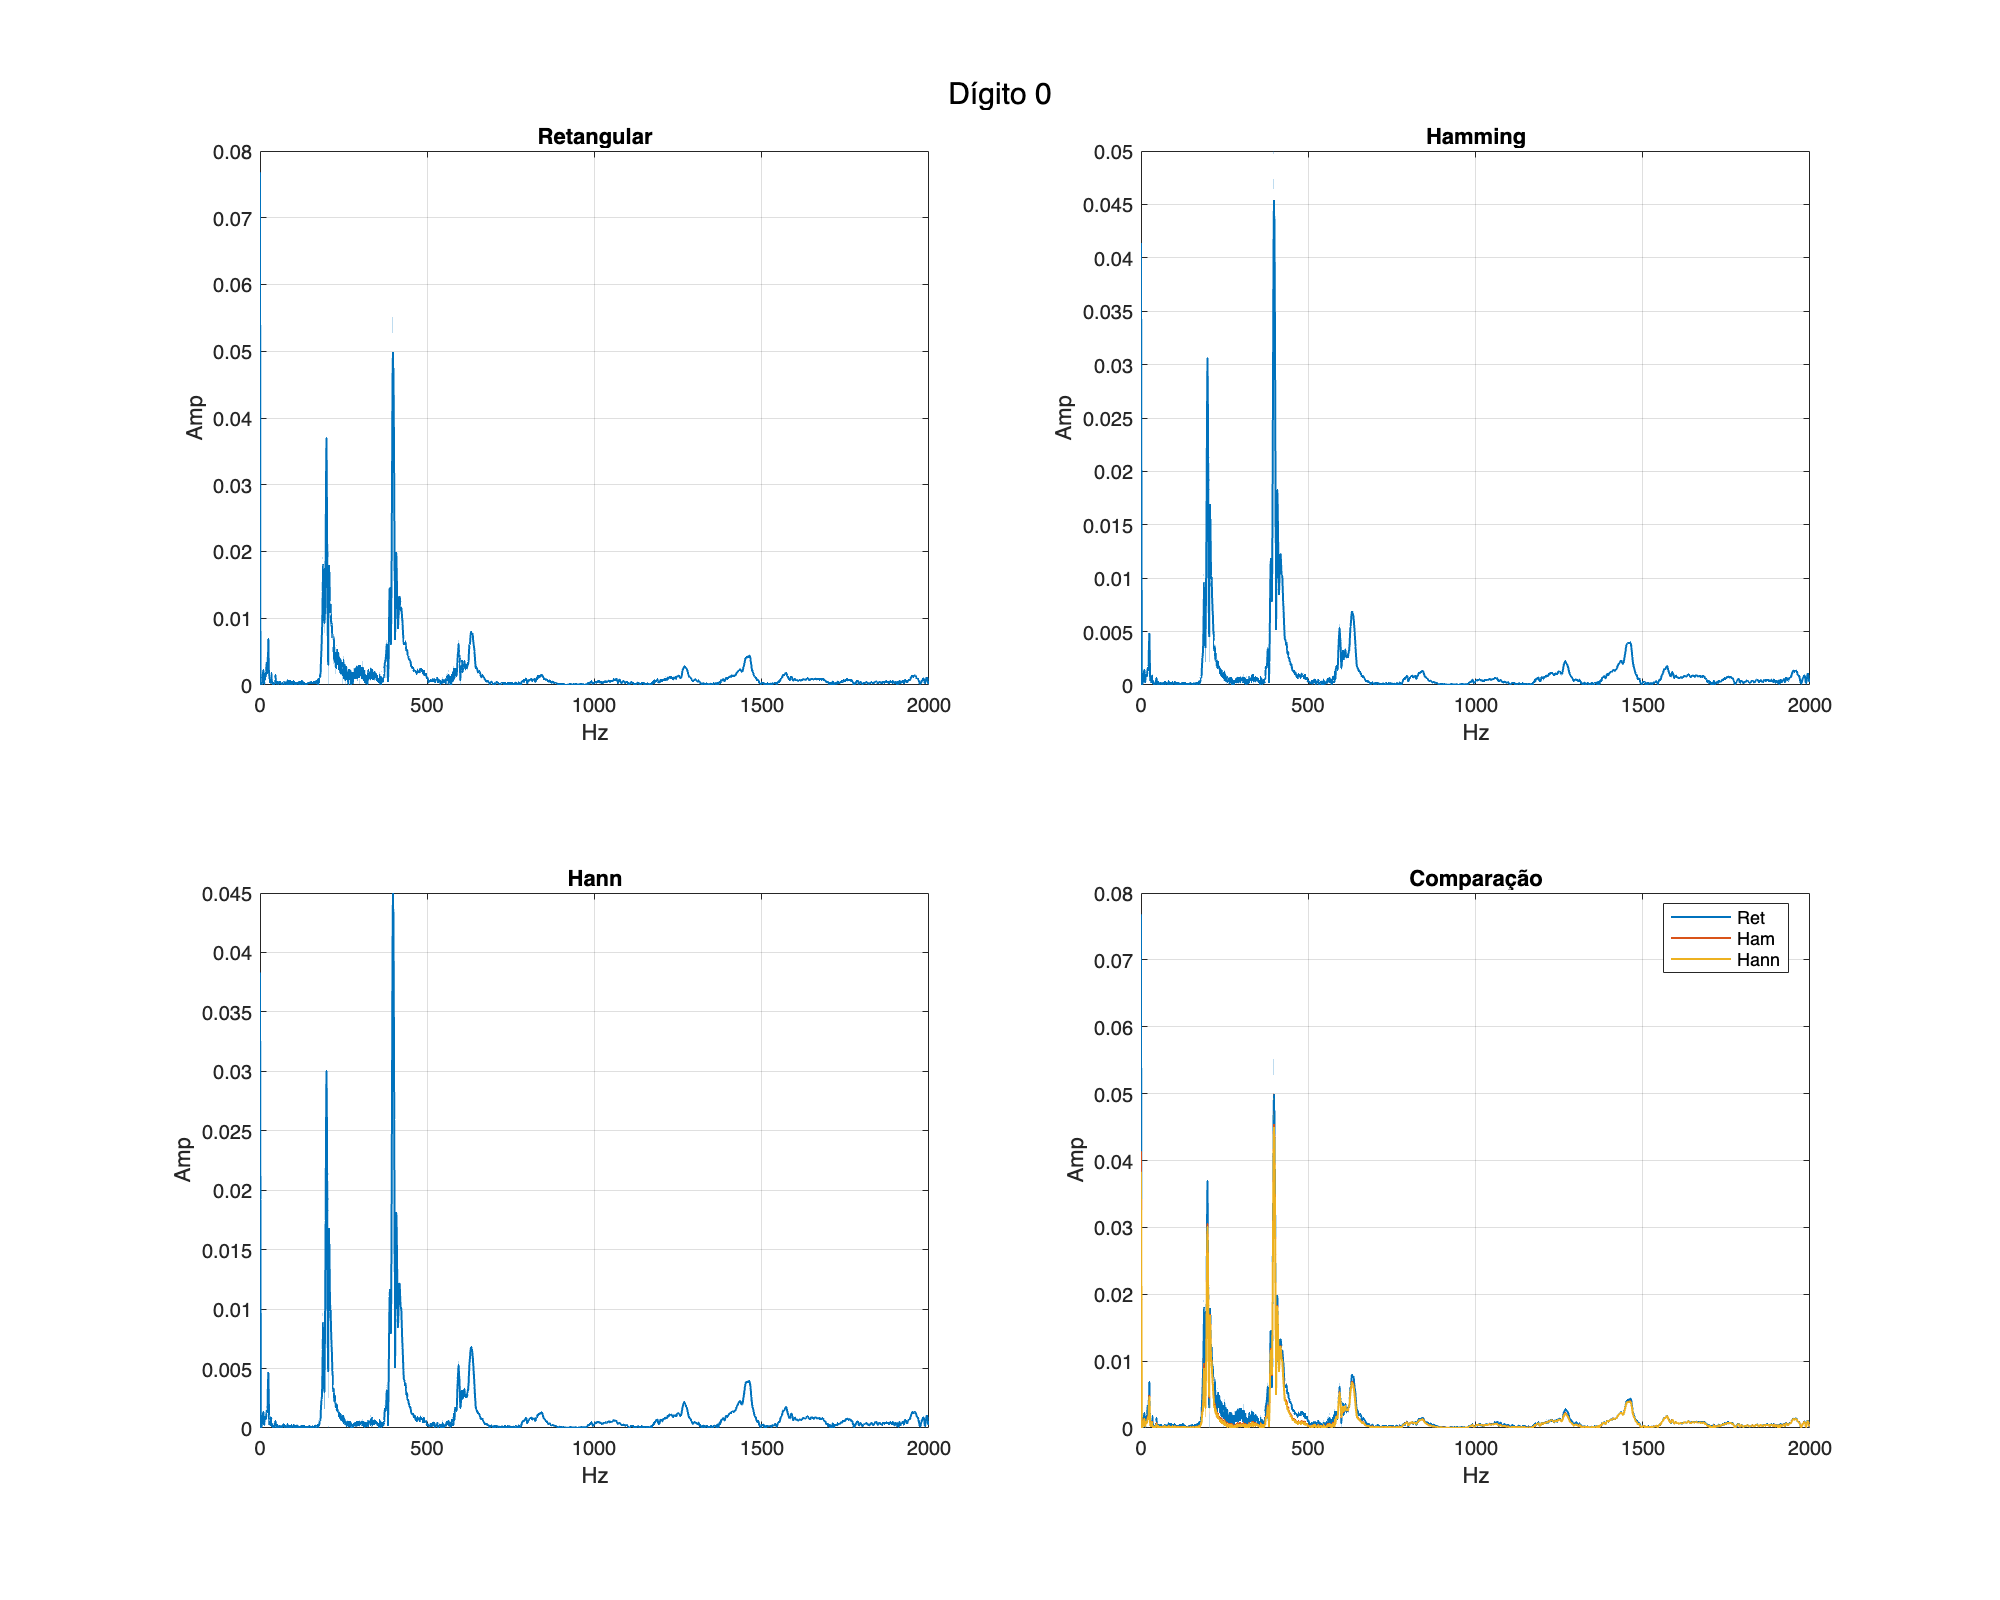

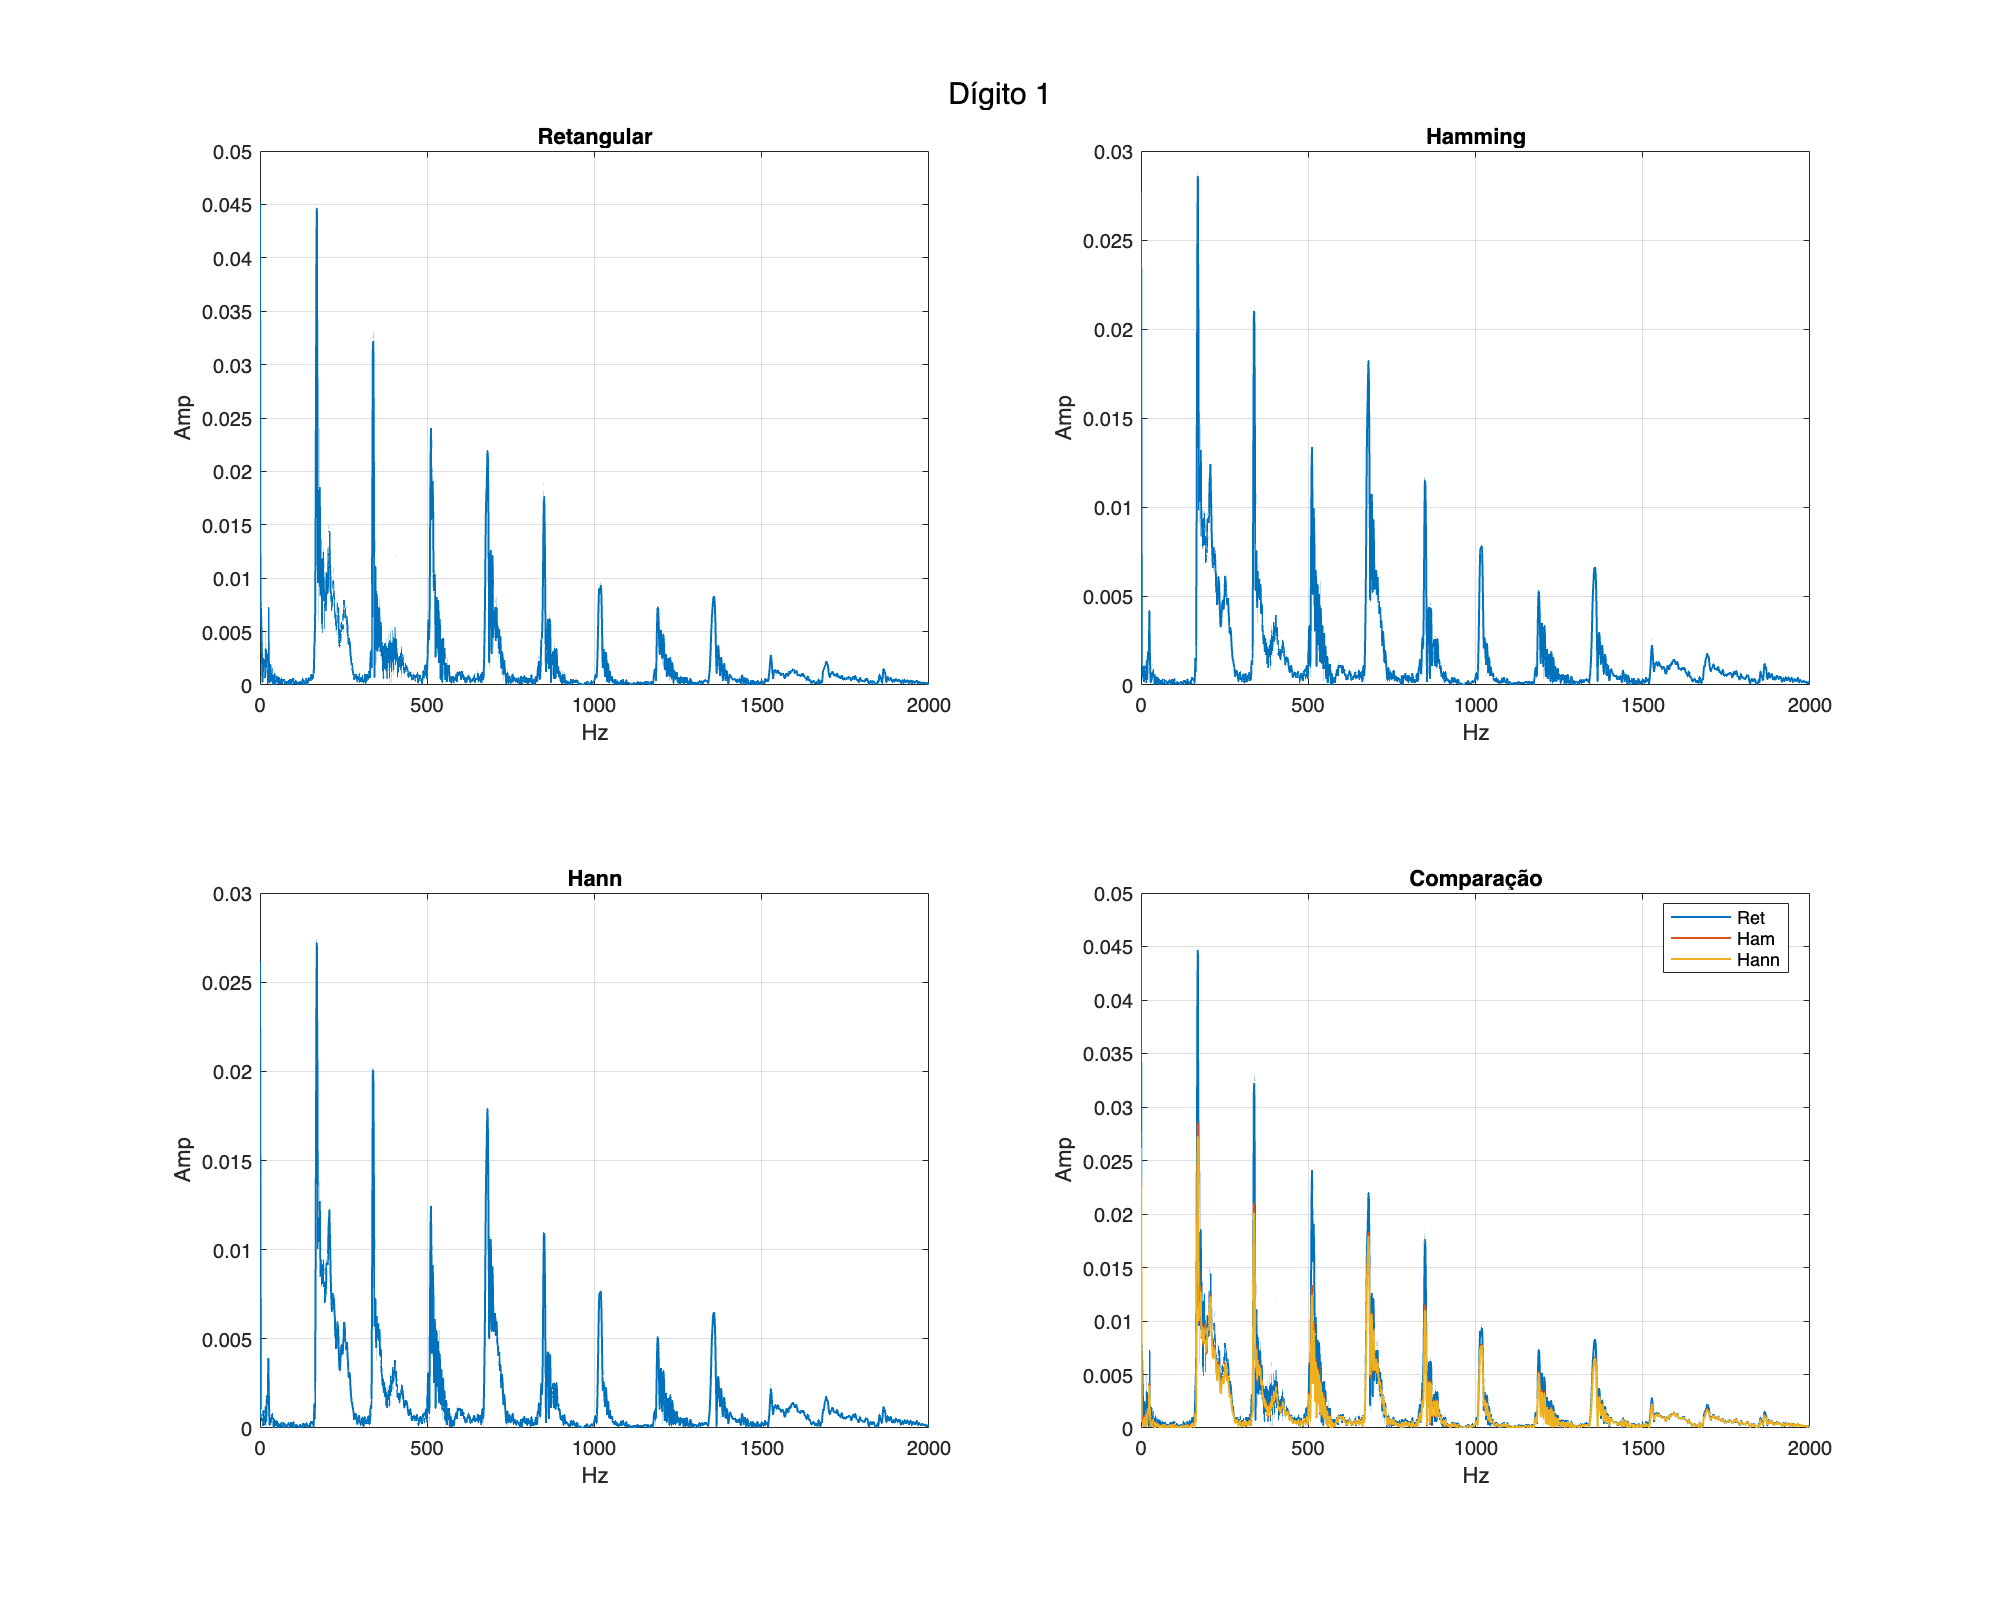

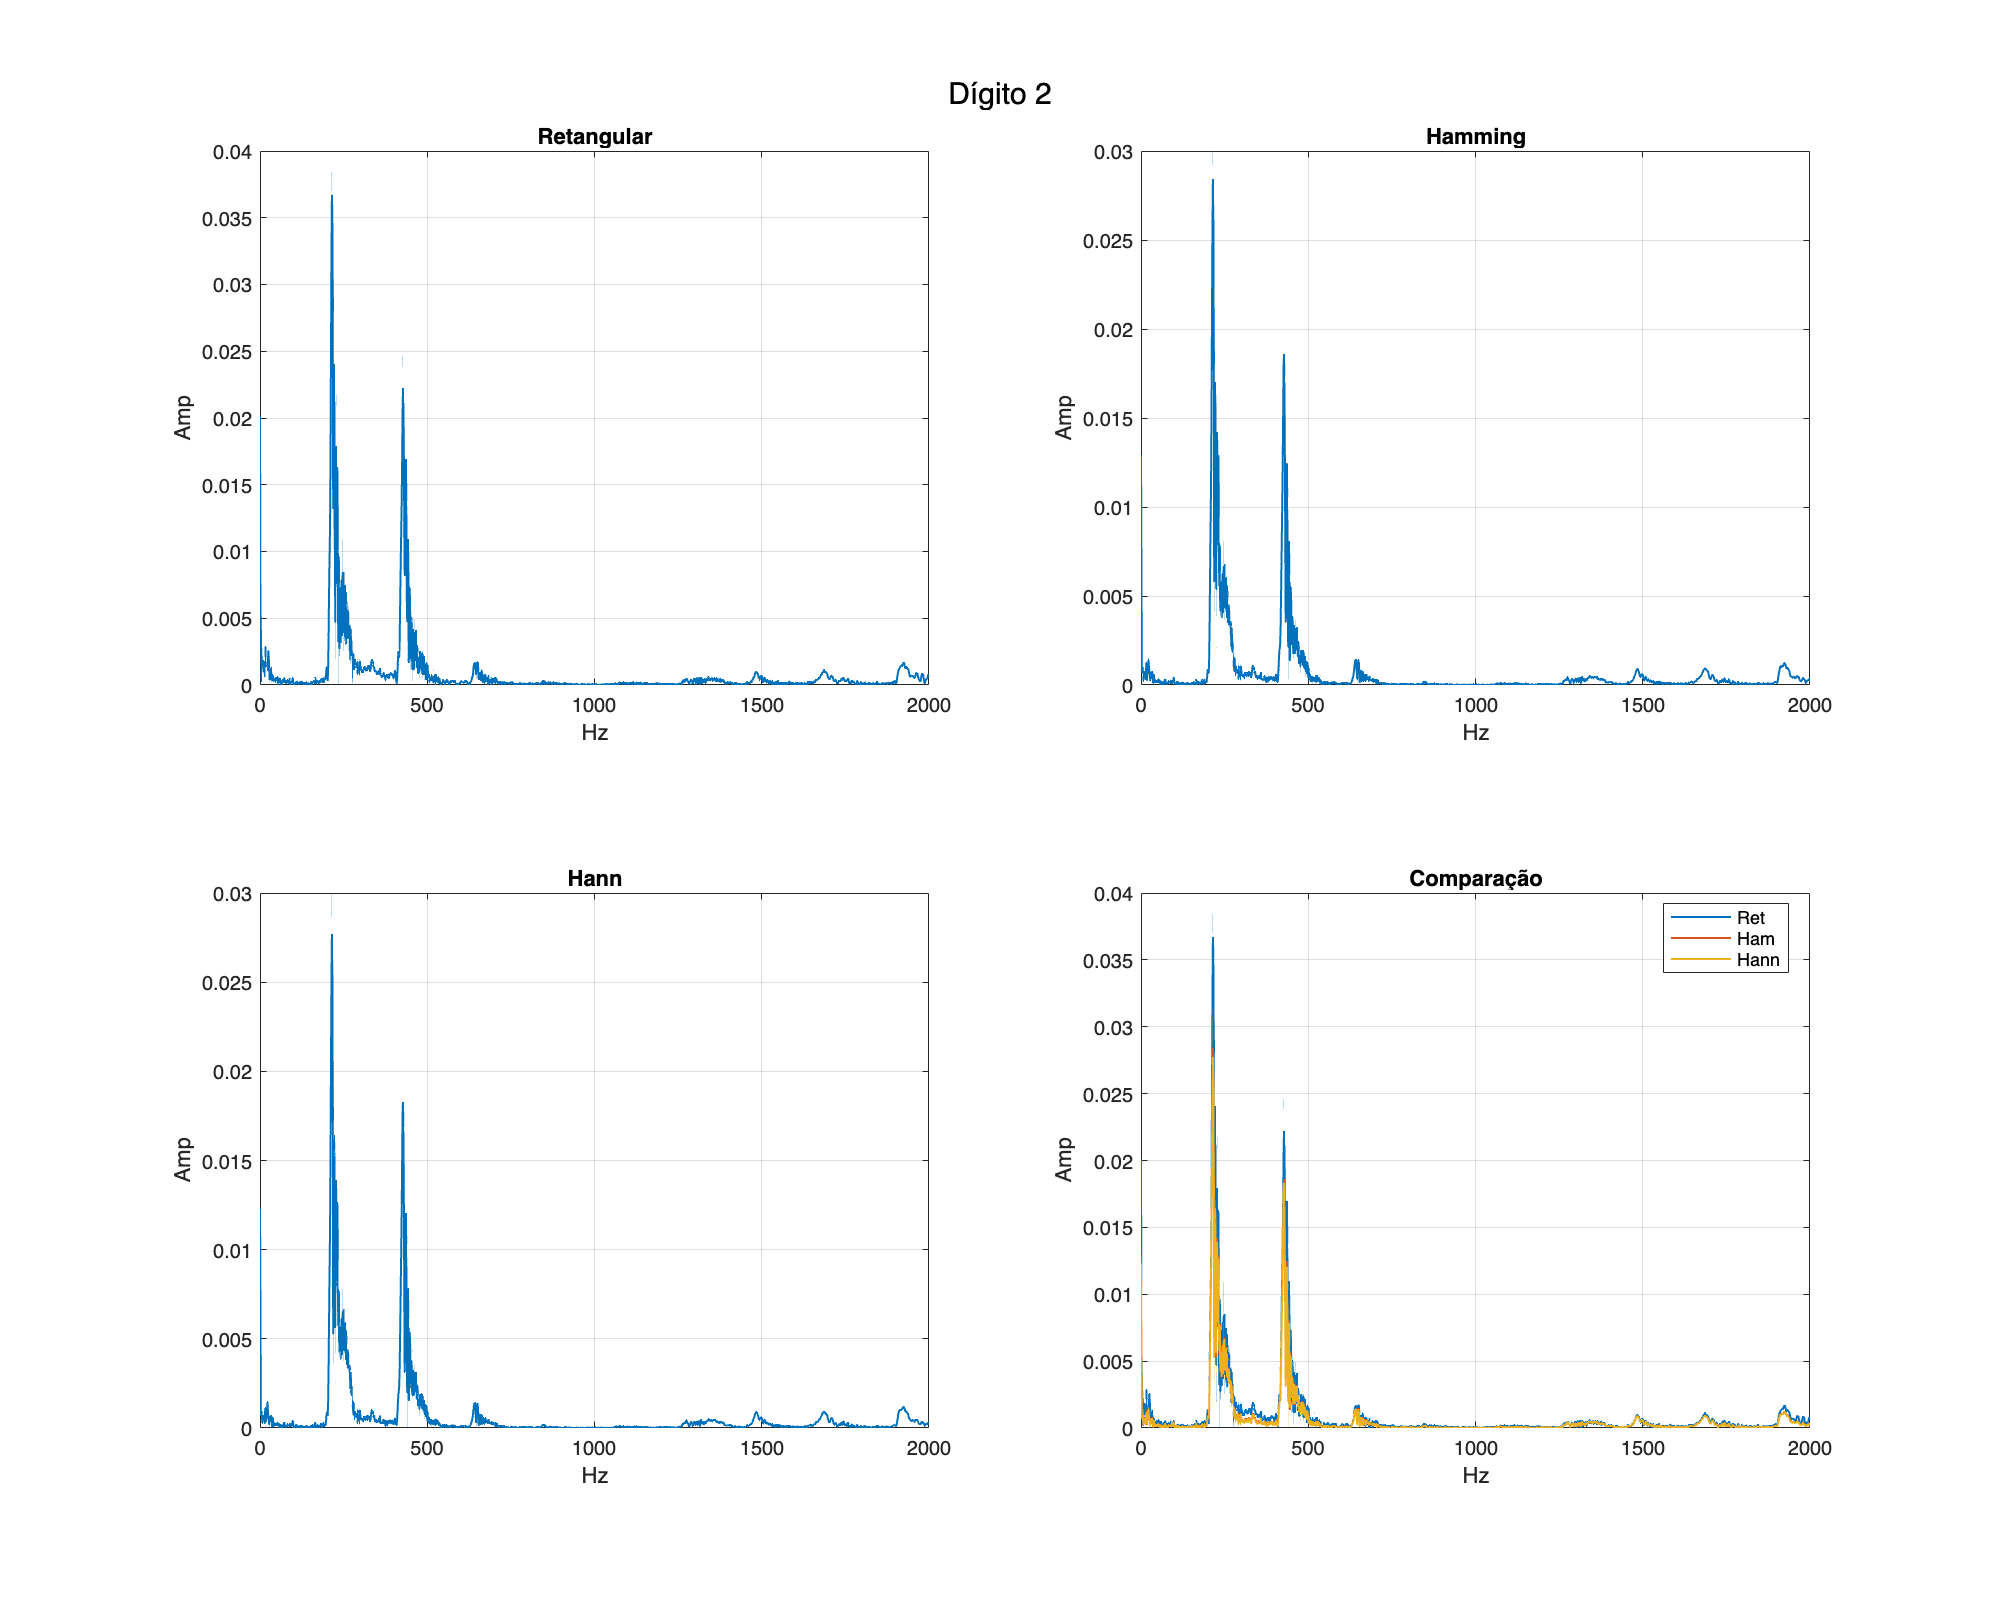

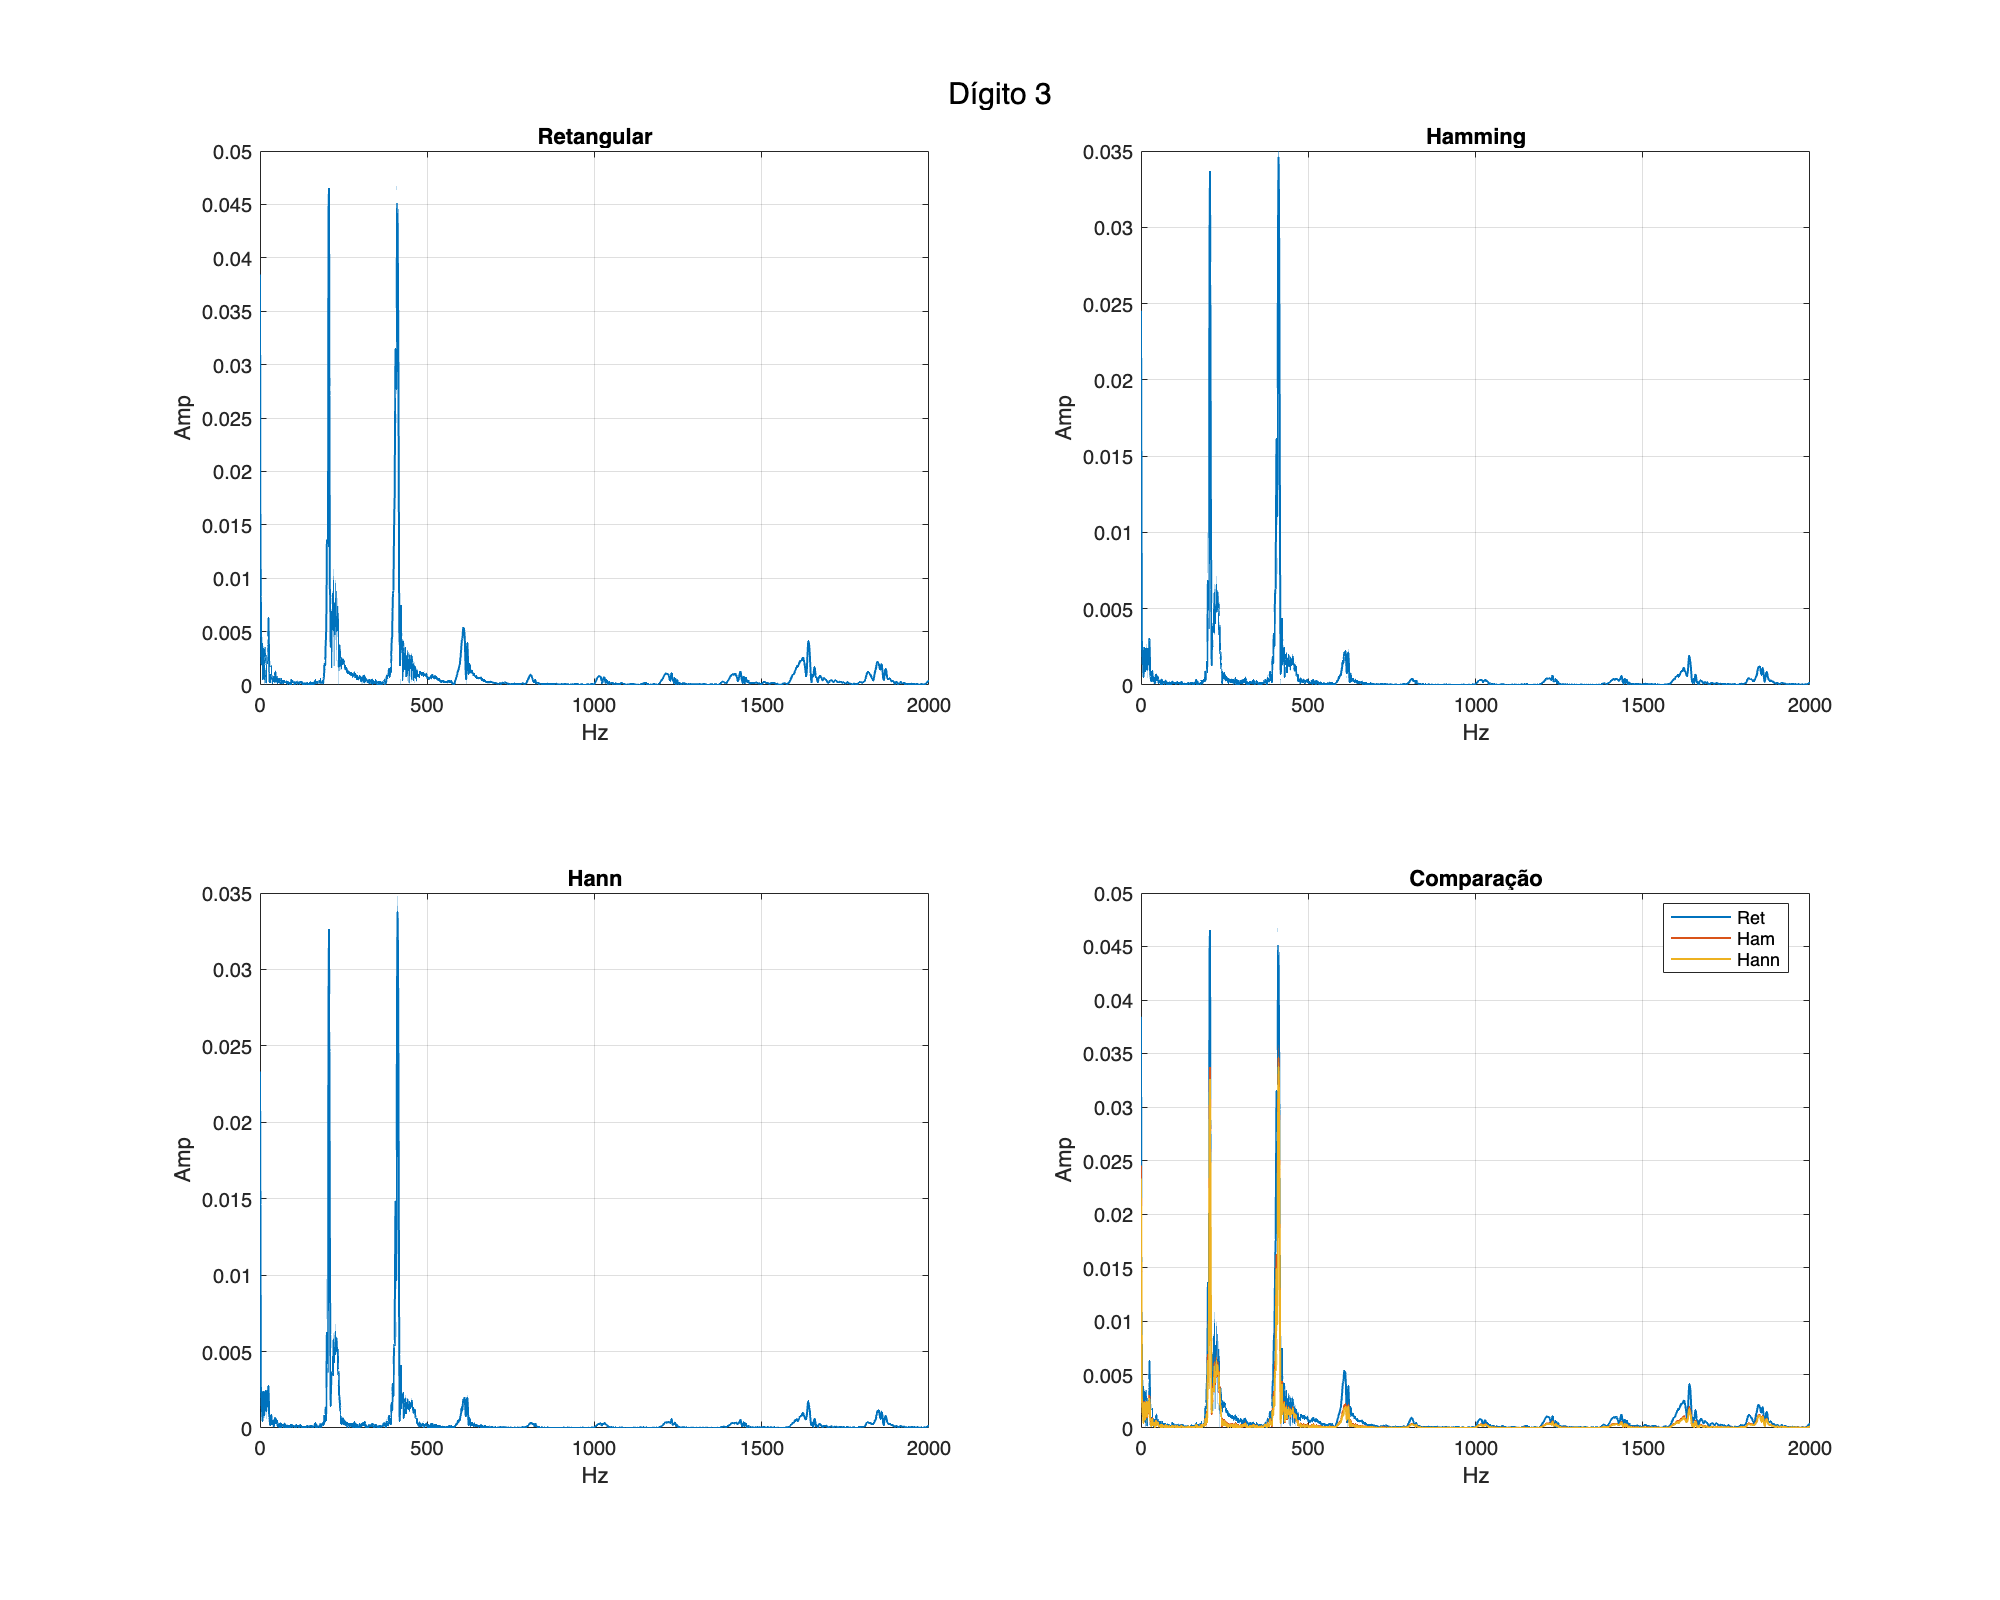

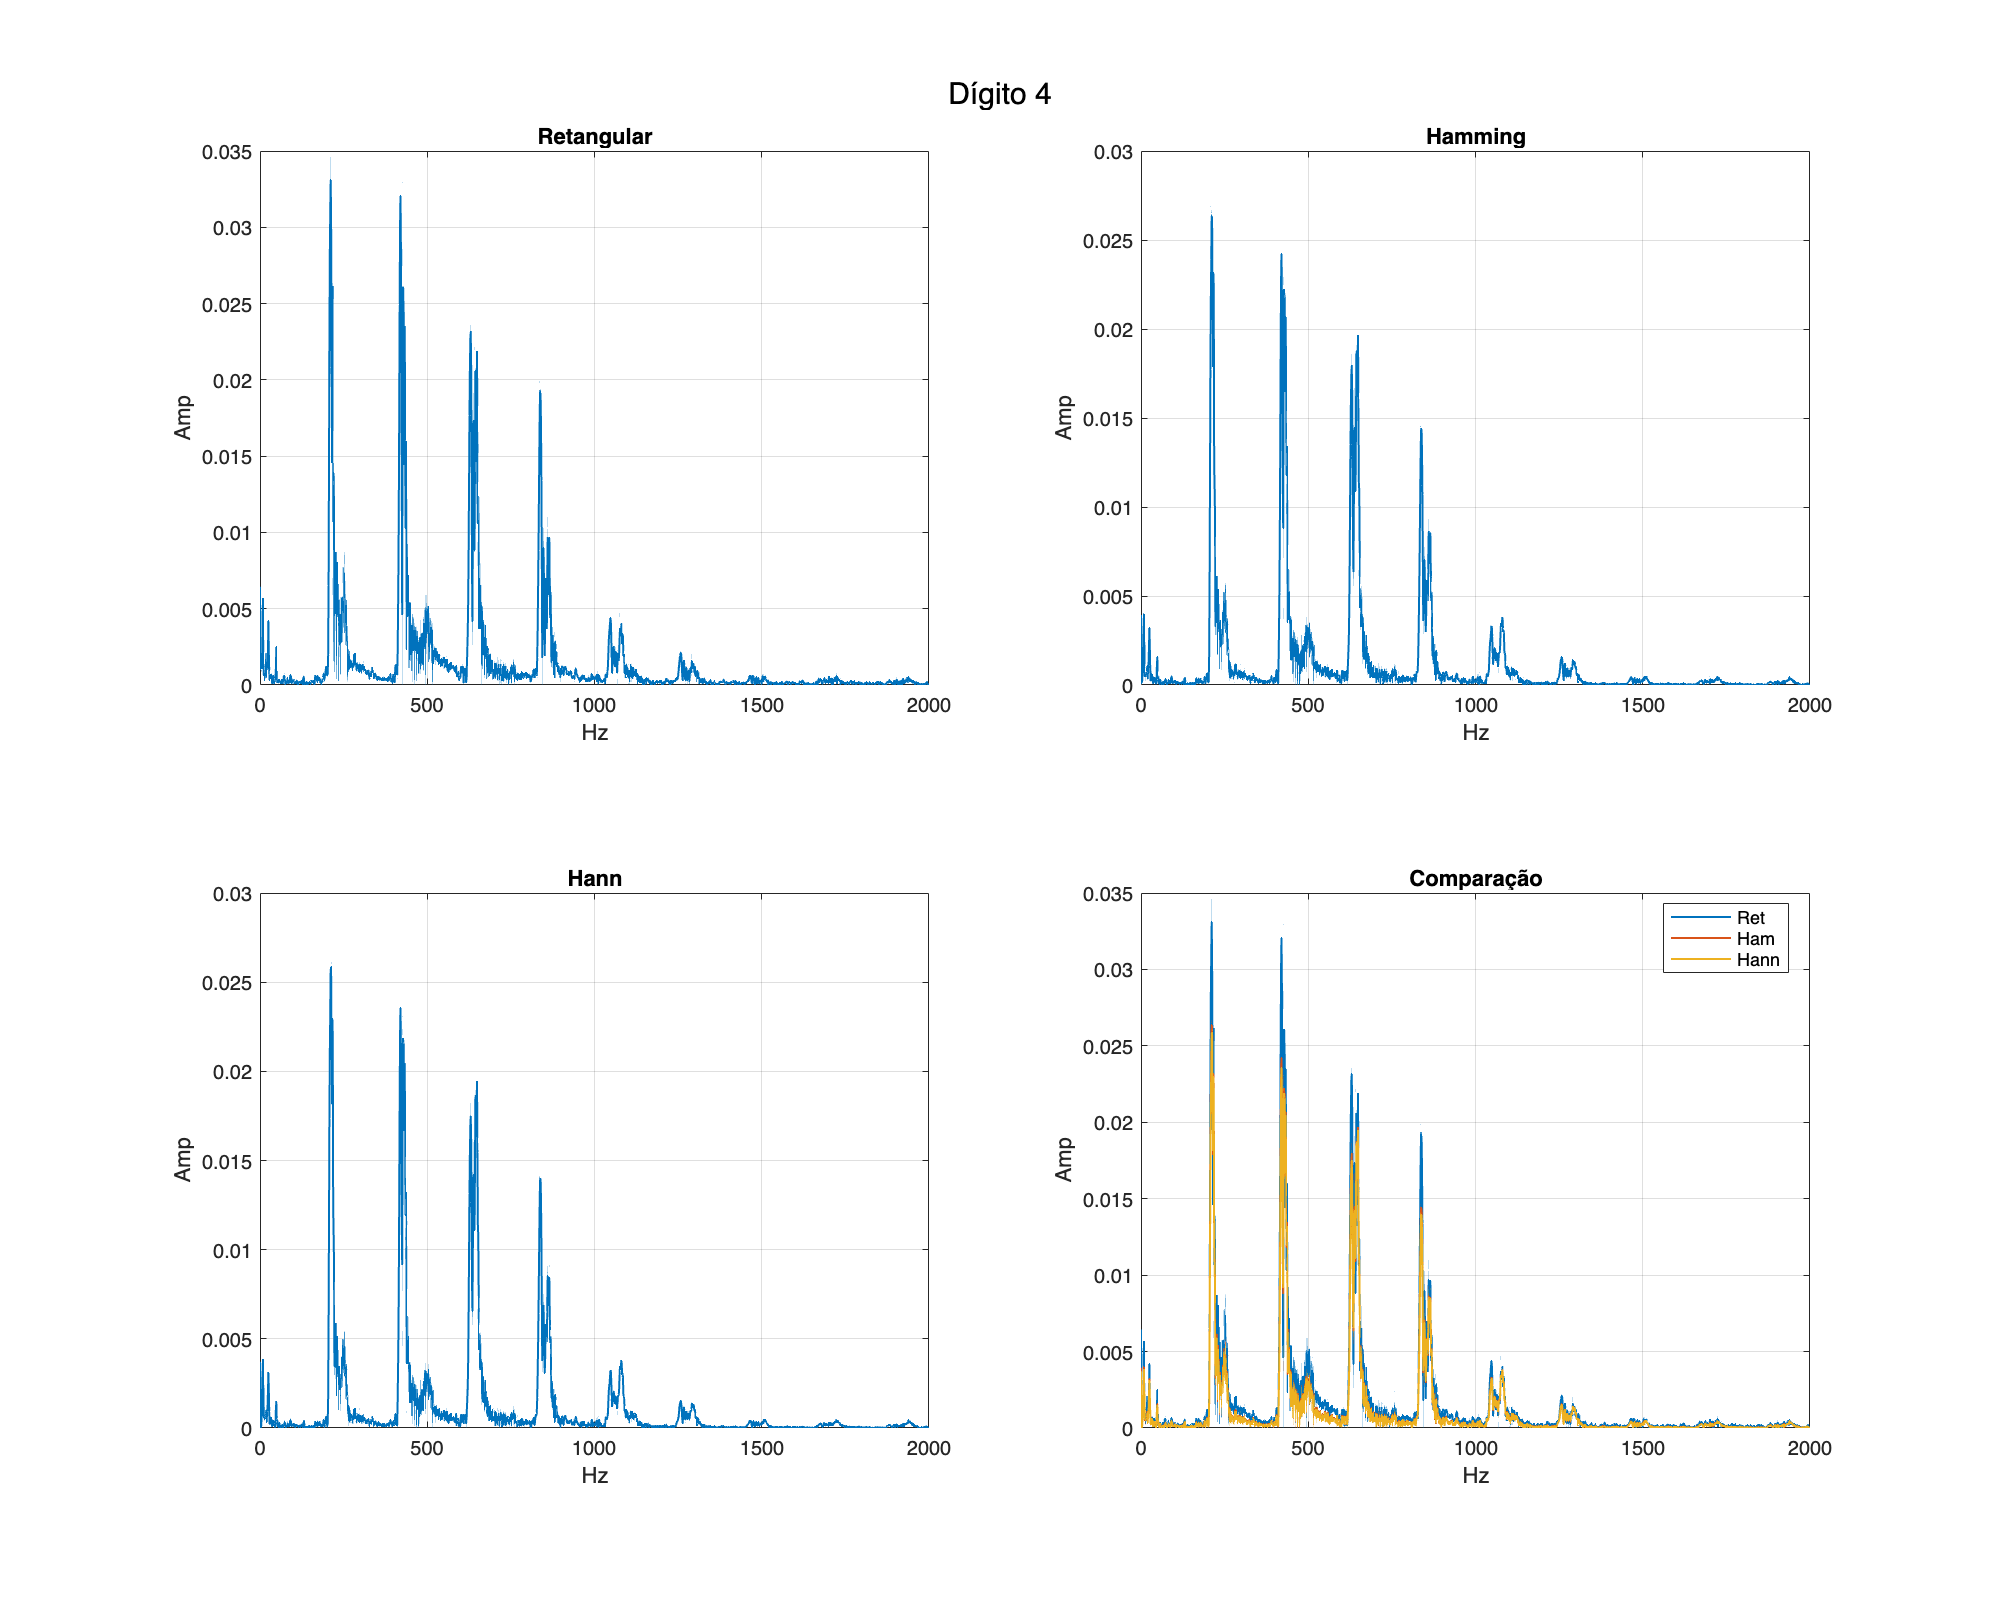

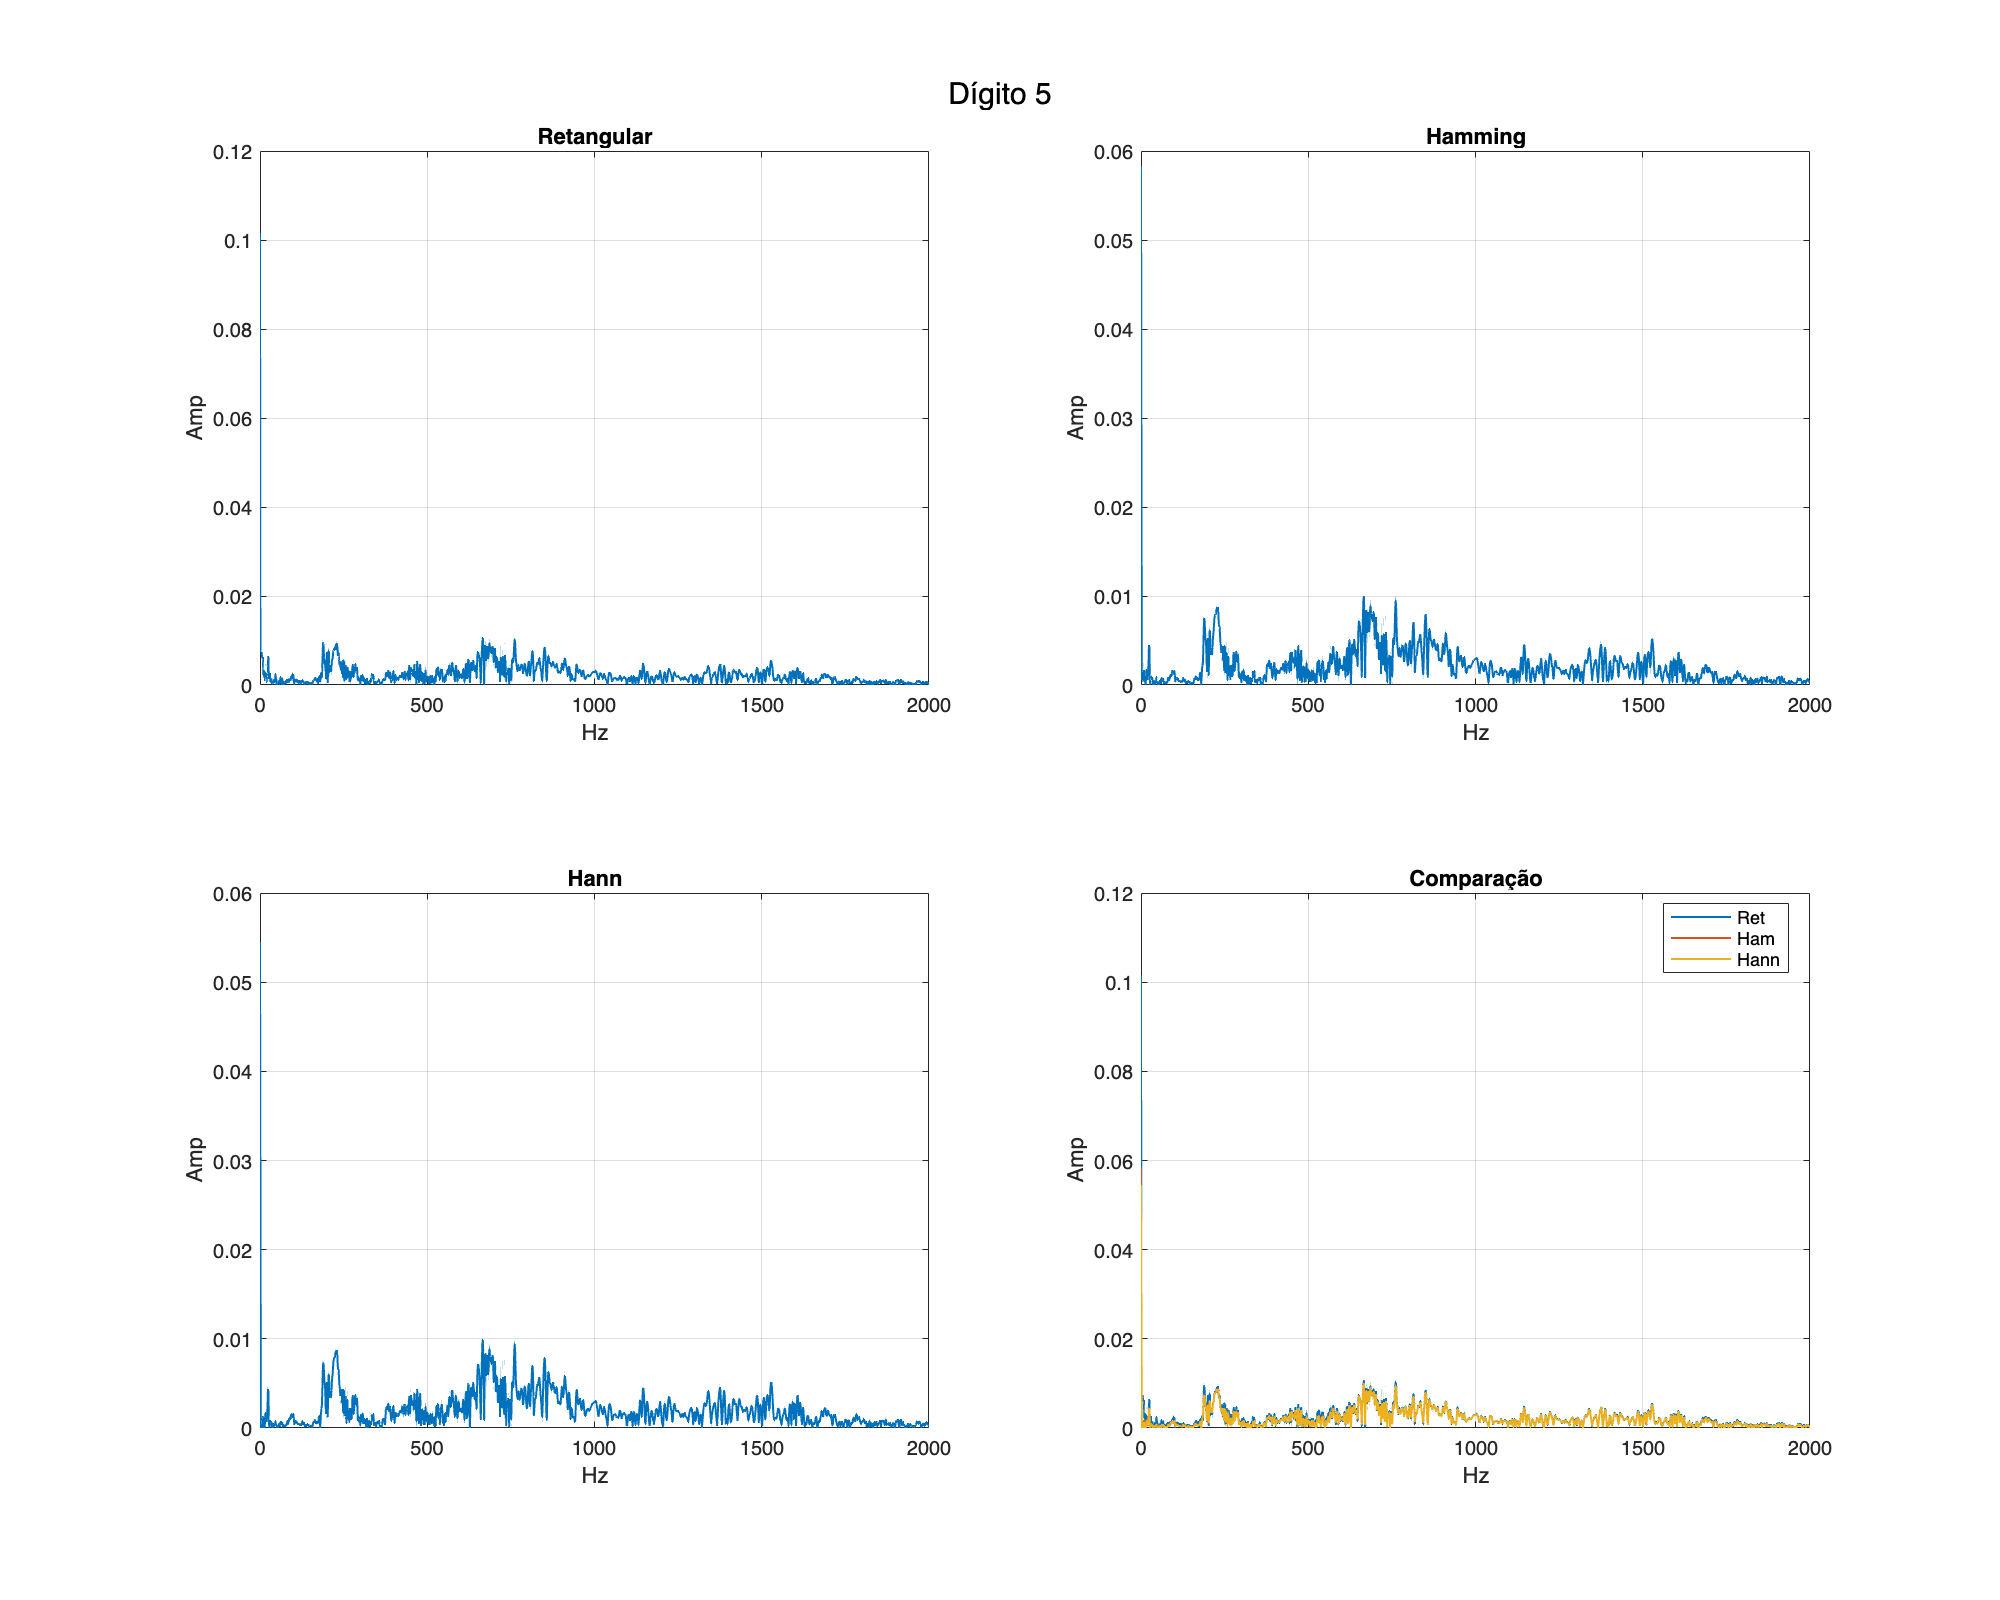

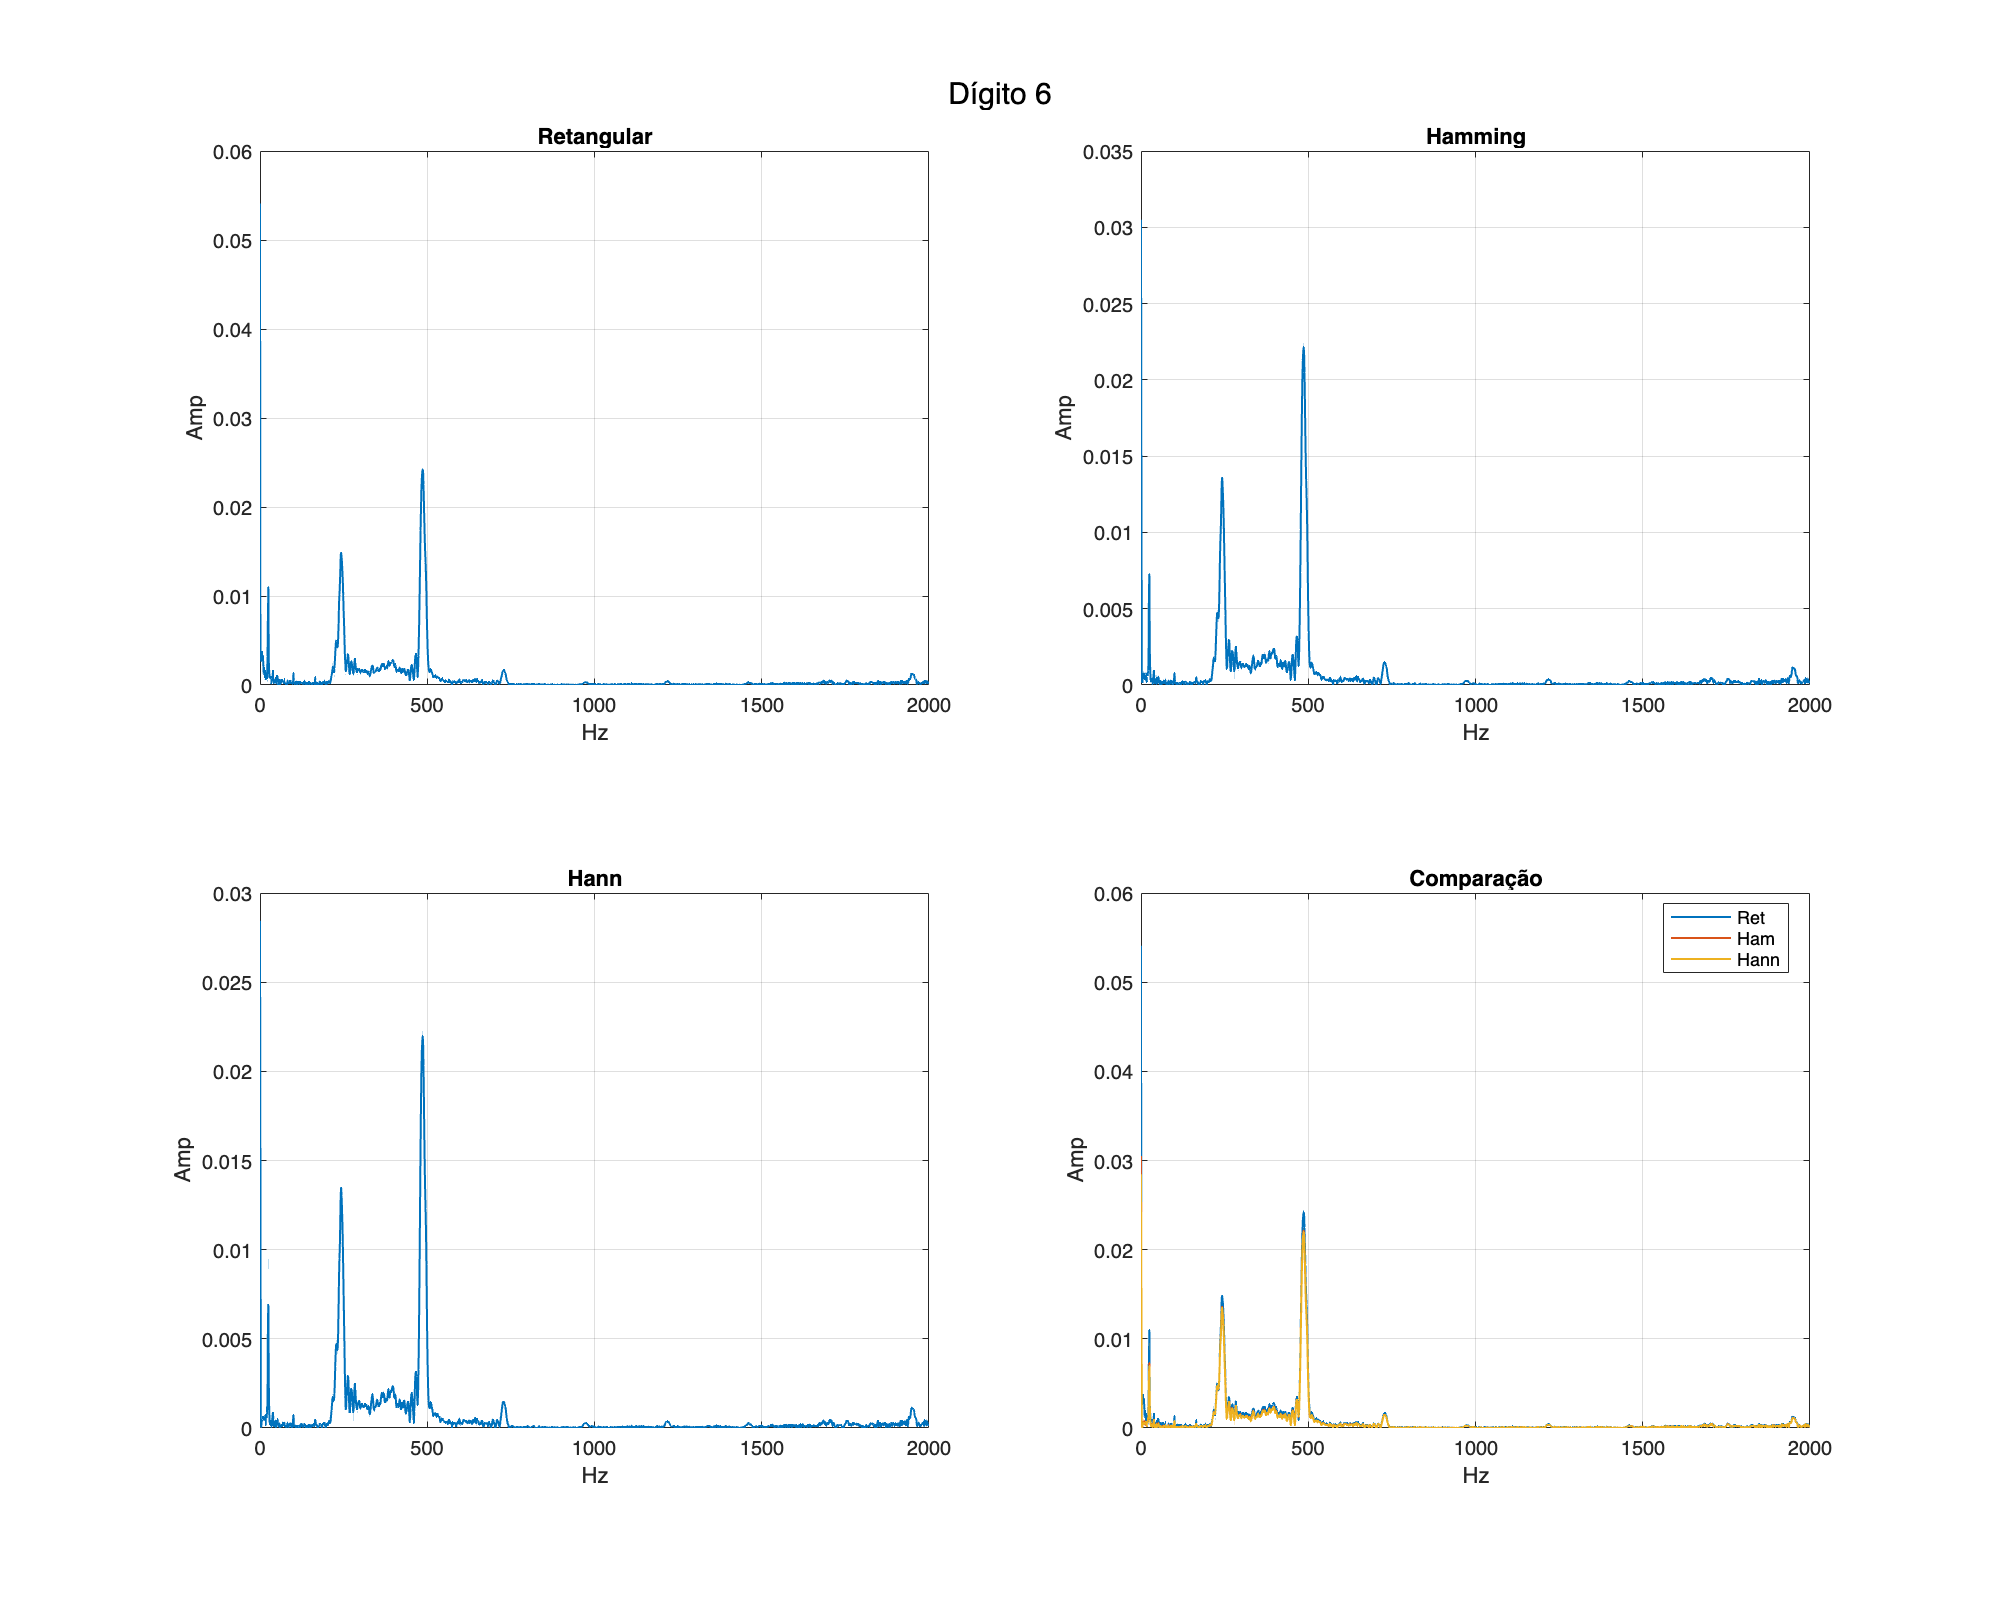

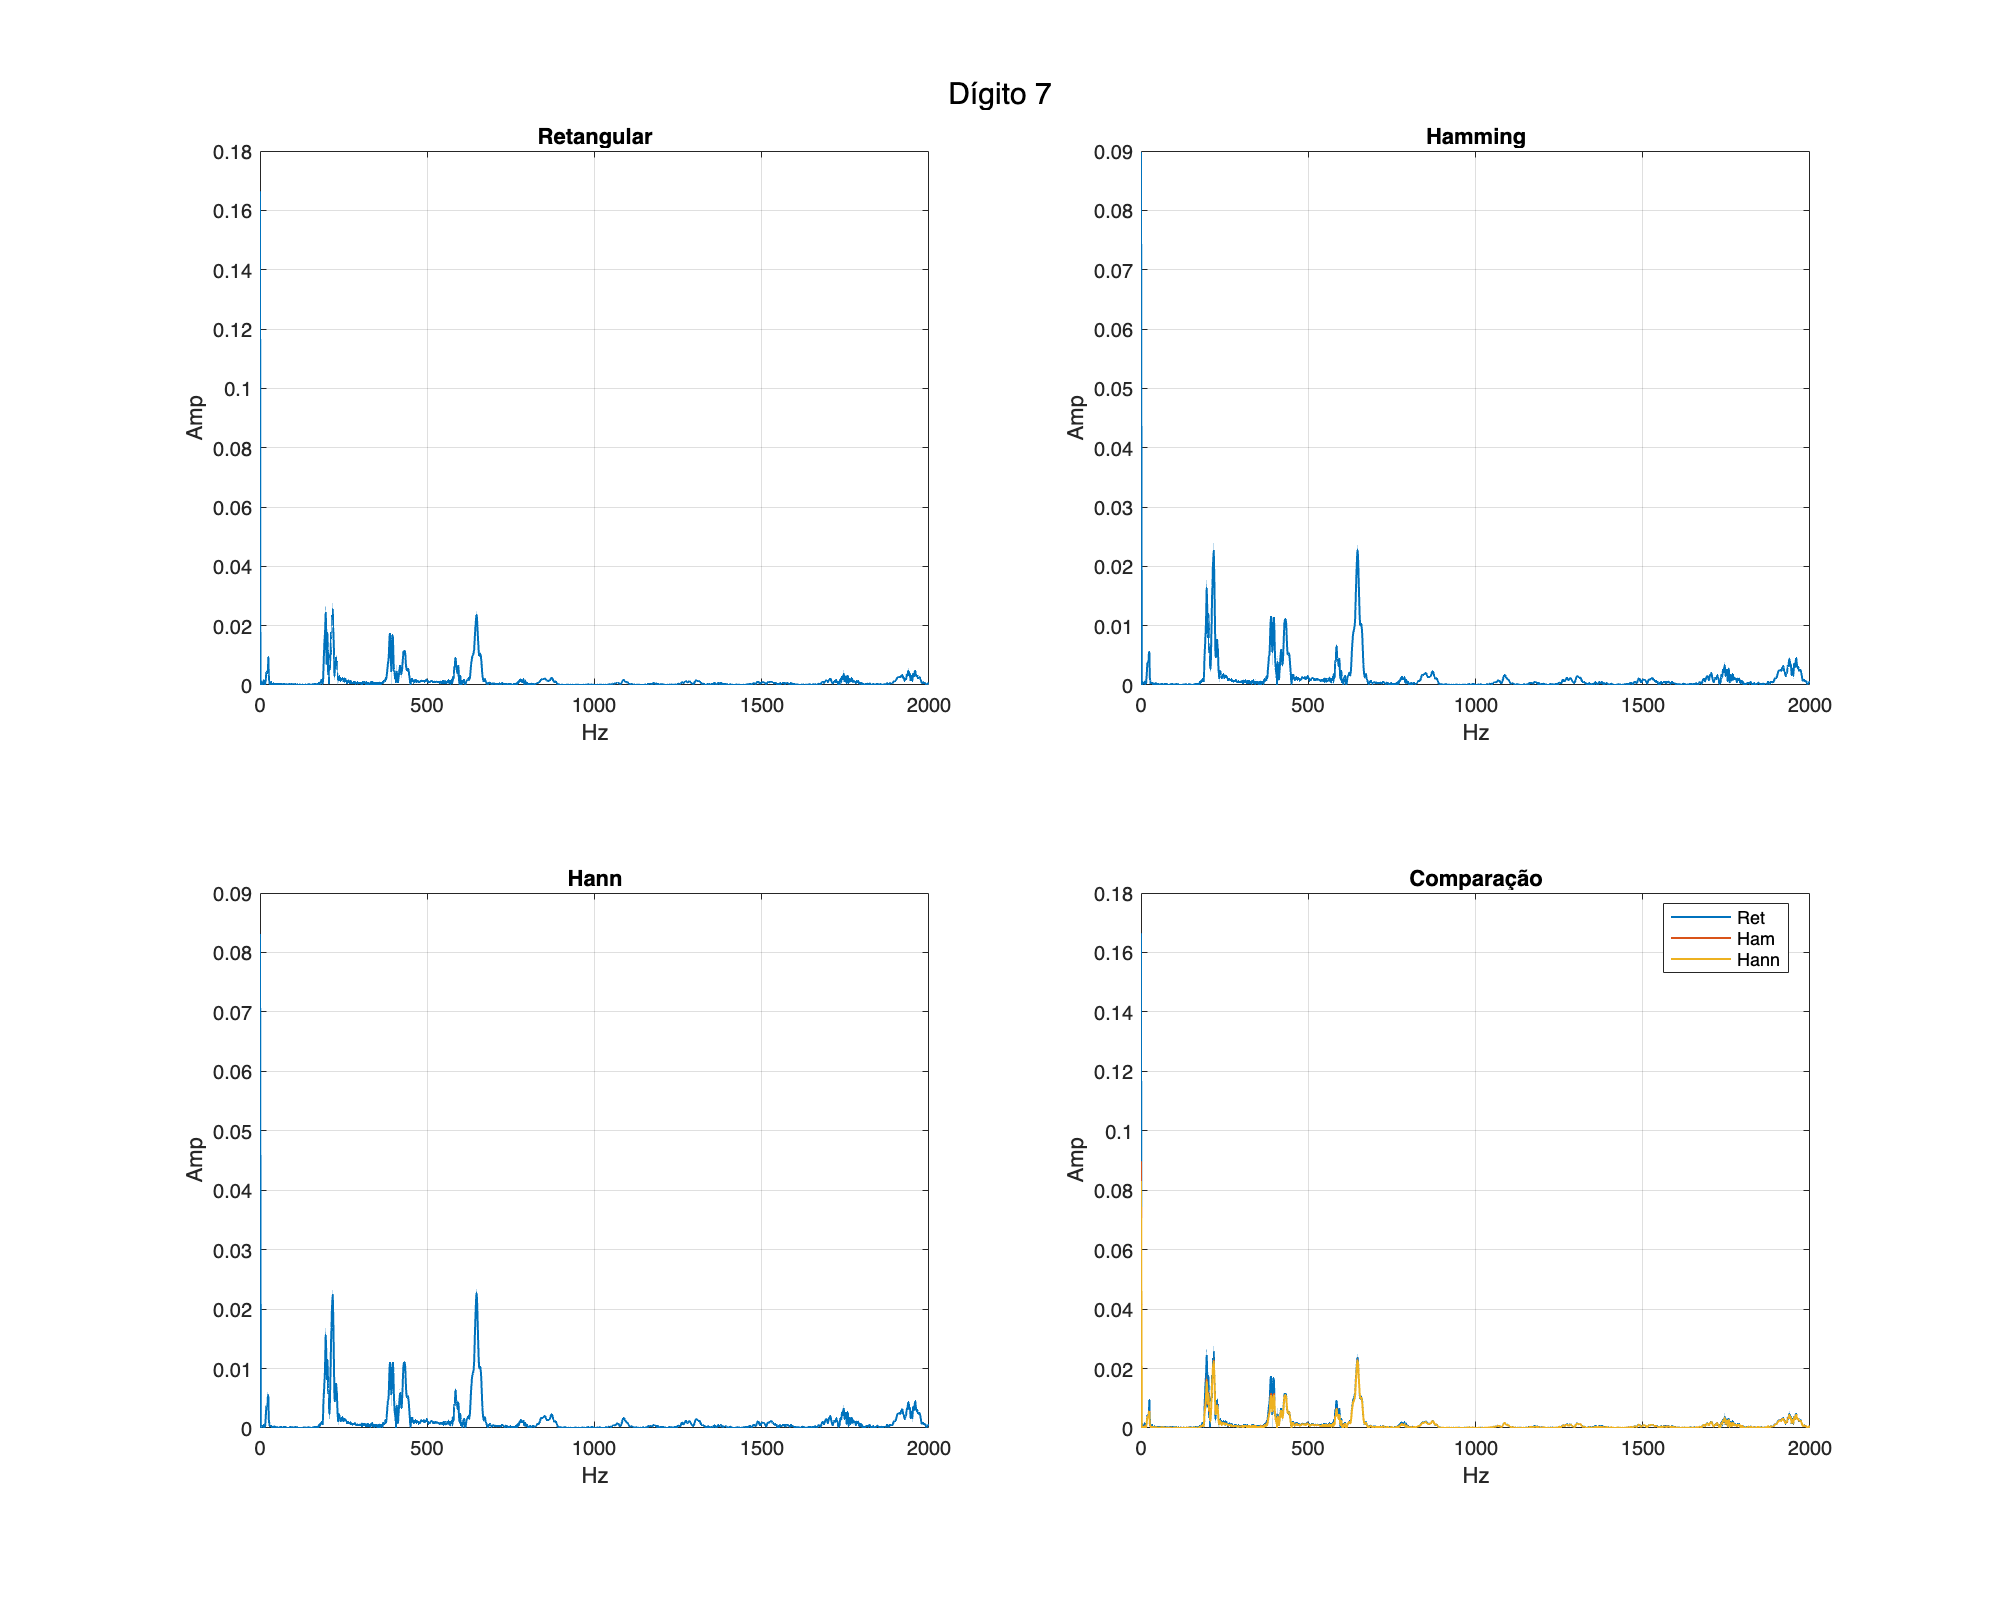


%% Aplicação de Janelas e Espectros para cada Dígito
digitos_all = unique(y);
for k = 1:numel(digitos_all)
    idx = find(y==digitos_all(k),1);
    s = tabela.Sinal_Processado{idx}; fs = tabela.Taxa_Amostragem(idx);
    N = length(s); t = (0:N-1)/fs;
    % aplicar janelas
    w_rect    = ones(N,1);
    w_hamming = hamming(N);
    w_hann    = hann(N);
    S_rect    = fft(s.*w_rect)/N;
    S_hamming = fft(s.*w_hamming)/N;
    S_hann    = fft(s.*w_hann)/N;
    nFreq = floor(N/2)+1; freq = (0:nFreq-1)*fs/N;
    idx2000 = freq<=2000; f2000=freq(idx2000);
    ampR = abs(S_rect(1:nFreq)); ampH = abs(S_hamming(1:nFreq)); ampN = abs(S_hann(1:nFreq));
    ampR = ampR(idx2000); ampH = ampH(idx2000); ampN = ampN(idx2000);
    % plot espectros (2x2)
    figure('Name',sprintf('Dígito %d - Espectros de Janelas',digitos_all(k)), ...
           'NumberTitle','off','Position',[100 100 1000 800]);
    sgtitle(sprintf('Dígito %d', digitos_all(k)));
    subplot(2,2,1);
    plot(f2000, ampR, 'LineWidth',1); title('Retangular'); xlabel('Hz'); ylabel('Amp'); xlim([0 2000]); grid on;
    subplot(2,2,2);
    plot(f2000, ampH, 'LineWidth',1); title('Hamming');    xlabel('Hz'); ylabel('Amp'); xlim([0 2000]); grid on;
    subplot(2,2,3);
    plot(f2000, ampN, 'LineWidth',1); title('Hann');       xlabel('Hz'); ylabel('Amp'); xlim([0 2000]); grid on;
    subplot(2,2,4);
    plot(f2000, ampR, 'LineWidth',1); hold on; plot(f2000, ampH, 'LineWidth',1); plot(f2000, ampN, 'LineWidth',1);
    title('Comparação'); xlabel('Hz'); ylabel('Amp'); legend('Ret','Ham','Hann','Location','best'); xlim([0 2000]); grid on;
end


%% Comentários
% O gráfico de janelas é mostrado somente uma vez com cores mais visíveis.
% Em seguida, para cada dígito, são gerados espectros em subplots 2×2.
